# **Result 1: Global evidence of social inequality on flooding duration**

**Assumption: **Poorer country may experience longer flooding duration.

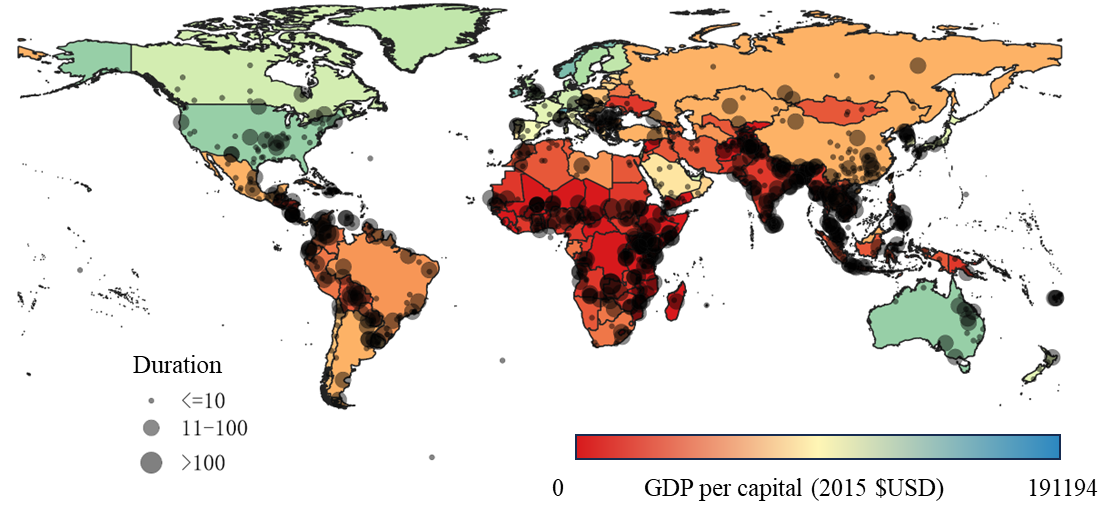

**Fig 1.****GDP and flood duration. **This map displays 998 major flood disasters (dots) that occurred between 2000 and 2023, with the size of the dots indicating the duration of these floods, and the colour of the countries indicating their GDP per capital.

## Prepare Data: The GDP per capital, The inequality value, The duration of each events

也可以直接在QGIS中画图

重点，准备好数据：

通过国家名匹配

计算每个时间的duration

N_event = size(public_emdat_flood(:,"DisNo_"),1);

duration = zeros(N_event,1);

endyear = table2array(public_emdat_flood(:,"EndYear"));
endmonth = table2array(public_emdat_flood(:,"EndMonth"));
endday = table2array(public_emdat_flood(:,"EndDay"));

stayear = table2array(public_emdat_flood(:,"StartYear"));
stamonth = table2array(public_emdat_flood(:,"StartMonth"));
staday = table2array(public_emdat_flood(:,"StartDay"));

for ni = 1:N_event
    duration(ni) = days(datetime(endyear(ni), ...
                        endmonth(ni), ...
                        endday(ni))- ...
                        datetime(stayear(ni), ...
                        stamonth(ni), ...
                        staday(ni)));

end

将洪涝事件分类，分类标准为灾害发生年份的该国家的GDP

形成一个对照表，一列是flood duration，

首先填充GDP表格，相邻时间。


% GDP_per_capital_2015{:, 5:27}(GDP_per_capital_2015{:, 5:27} == 0) = NaN;
% GDP_T = fillmissing(rows2vars(GDP_per_capital_2015(:,5:27)), ...
%     'nearest', 'DataVariables', @isnumeric);
% 
% GDP_T_T = rows2vars(GDP_T(1:end,2:end));
% GDP_per_capital_2015(:,5:27) = GDP_T_T(:,2:end);

event_country_code = table2array(public_emdat_flood(:,"ISO"));

duration(:,2) = 1:length(duration(:,1));
events_with_dura = duration(duration(:,1)>0,2);


duration_gdppc = zeros(sum(duration(:,1)>0),3);
duration_gdppc(:,1) = events_with_dura;

for ei=1:length(duration_gdppc(:,1))
    duration_gdppc(ei,2) = duration(events_with_dura(ei));
    coun_code = event_country_code(events_with_dura(ei));
    coun_col = table2array(GDP_per_capital_2015(:,"CountryCode")) == char(coun_code);

    if sum(coun_col)==1
        eve_year = stayear(events_with_dura(ei));
        if eve_year<2000
            eve_year = 2000;
        elseif eve_year>2022
            eve_year = 2022;
        end
        
        
        event_GDP_pc = table2array(GDP_per_capital_2015(coun_col, ...
            strcat("x",num2str(eve_year),"_YR",num2str(eve_year),"_")));
        duration_gdppc(ei,3) = event_GDP_pc;
    end
end





按GDP分类

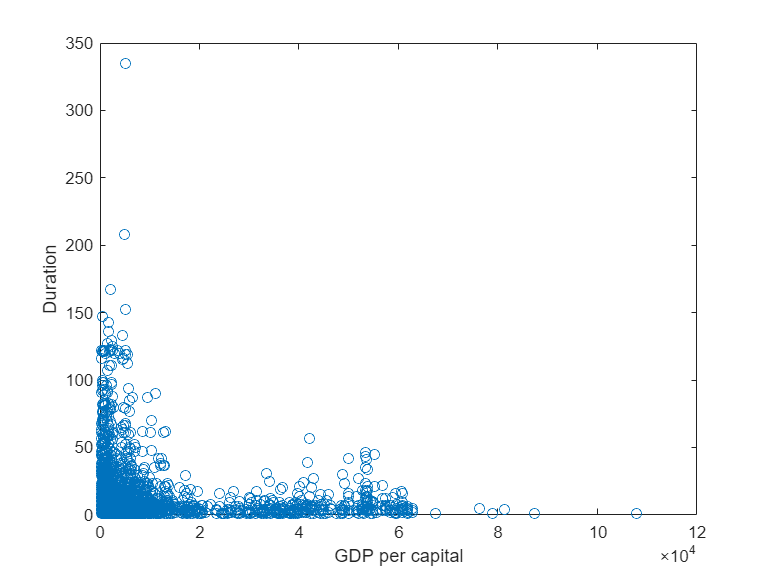

duration_gdppc_nonzero = duration_gdppc(duration_gdppc(:,3)>0,:);

figure
plot(duration_gdppc_nonzero(:,3),duration_gdppc_nonzero(:,2),'o');
xlabel("GDP per capital");
ylabel("Duration");

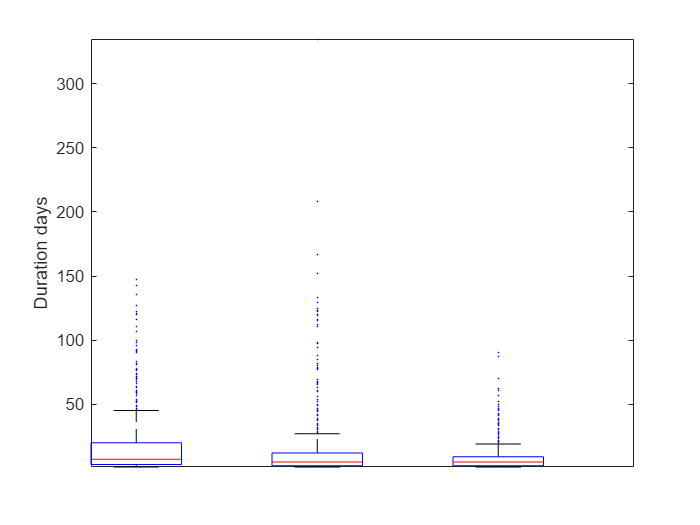

sort_duration_gdppc_nonzero = sortrows(duration_gdppc_nonzero,3);

group_low = sort_duration_gdppc_nonzero(1:1015,:);
group_mid = sort_duration_gdppc_nonzero(1016:1015*2,:);
group_hig = sort_duration_gdppc_nonzero(1015*2+1:end,:);

figure
boxes_plot({{group_low(:,2)},{group_mid(:,2)},{group_hig(:,2)}},0.1);
ylabel("Duration days")

% 进行 Wilcoxon 符号秩检验
[p1,h1,stats1] = ranksum(group_low(:,2),group_mid(:,2));
[p2,h2,stats2] = ranksum(group_low(:,2),group_hig(:,2));
[p3,h3,stats3] = ranksum(group_mid(:,2),group_hig(:,2));
% 输出 p 值和检验统计量
fprintf('low and middle p 值: %f\n', p1);

low and middle p 值: 0.000000


% fprintf('检验统计量: %f\n', stats.signedrank);



Regression

x = duration_gdppc_nonzero(:,3);
y = duration_gdppc_nonzero(:,2);

% 进行线性回归分析
mdl = fitlm(x,y);
% 显示回归模型的摘要
disp(mdl)

线性回归模型:
    y ~ 1 + x1

估计系数:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)         14.007       0.44003     31.831    3.3897e-192
    x1             -0.00018194    2.6308e-05    -6.9157     5.6484e-12


观测值数目: 3047，误差自由度: 3045
均方根误差: 20.5
R 方: 0.0155，调整 R 方 0.0151
F 统计量(常量模型): 47.8，p 值 = 5.65e-12


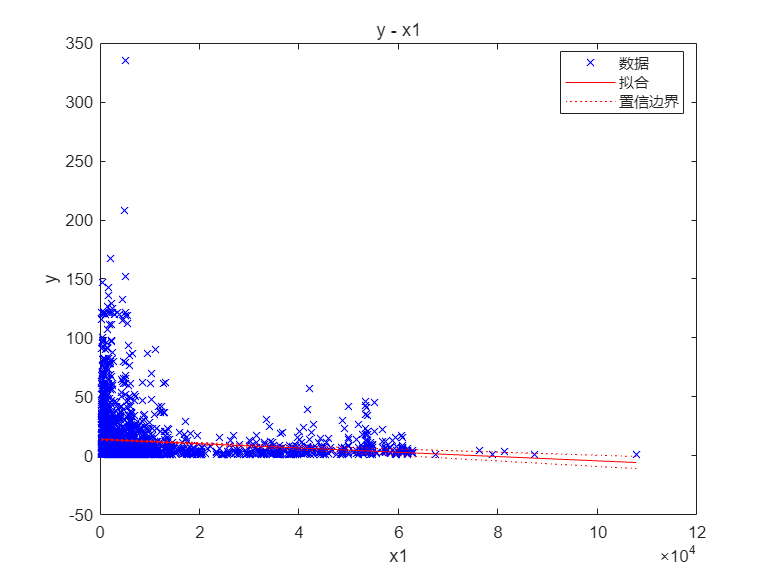

% 绘制回归线和散点图
figure
plot(mdl)